# Eksamen E2021

Mathias Bruun Houmøller  -  202006837

format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)
% latex(expr)

## Opgave 1 

Mathias Bruun Houmøller  -  202006837

a)

Data indskrives

clear
g = 9.81 %m/s2

g =          9.81


mp = 100 %kg

mp =    100


P = 250 %N

P =    250


S_1 = 0 %m

S_1 =      0


S_2 = 3 %m

S_2 =      3


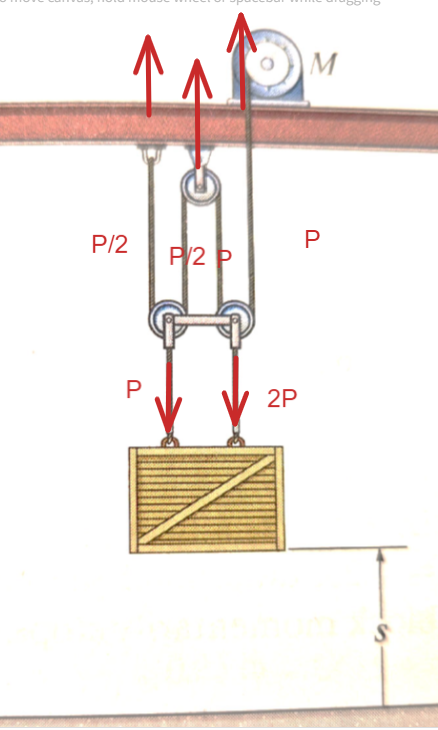

Vi indtegner krafter på billedet.

Løfstesystemet gør at der løftes med ekstra $2P$

og det ses således at der trækkes i kassem med $3P$

**b)**

Arbejdet fåes ved at integrer over afstanden der trækkes op

da S_1 = 0 går dette led ud

Da motoren løfter med P må resten af wire systemet løfte resnten af "energien" op


$$U _{wire}= \int_{S_1}^{S_2} F_G - P\ dS$$


syms s
U_wire = (mp * g - P) * S_2

U_wire =         2193


Arbejdet er således $U = 750\ J$

**c)**

**Potentiel energi kan beskrives som**


$$V = m \cdot g \cdot h$$


hvor vi har

$h_1 = S_1$ og $h_2 = S_2$

Der integreres fra $S_1$ til $S_2$ og da $S_1 = 0$ går dette led ud og vi ganger bare $S_2$ på

V_1 = mp * g * S_1

V_1 =      0


V_2 = mp * g * S_2

V_2 =         2943


**d)**

**Der er energi bevarelse og arbejdsligningen stilles op som**


$$V_1 + U_{motor} + U_{wire} = V_2$$


U_motor = P * S_2

U_motor =    750


displayFormula('V_1 + U_wire + U_motor == V_2')

$$0+2193+750=2943$$

venstre_side = V_1 + U_wire + U_motor

venstre_side =         2943


Det ses således at der er energibevarelse

**e)**

For at finde hastigheden på kassen divideres træk kræften med massen og der tage kvadrat roden af den endelige. Dette giver den korrekte endhed.

vi opstiller ligningen

da $P = m \cdot a$ og $v =  \sqrt{a \cdot S}$ så får vi


$$v = \sqrt\frac{P \cdot S_2}{m_p}$$


v = sqrt(P * S_2 / mp )

v =        2.7386


Hastigheden af kassen er således $2,74\ \frac{m}{s}$ 

## Opgave 2 

Mathias Bruun Houmøller  -  202006837

a)

Der antages konstant acceleration

**FBD **- $F_n$ er normal kraften $\alpha$ er vinkelacceleratione, $F_{frik}$ er fiktionskraften, $F_G$ er tyngde kraften

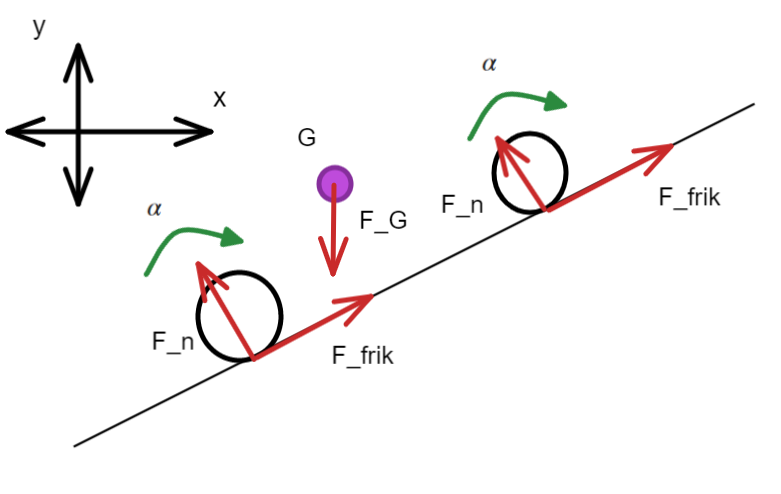

**KD**

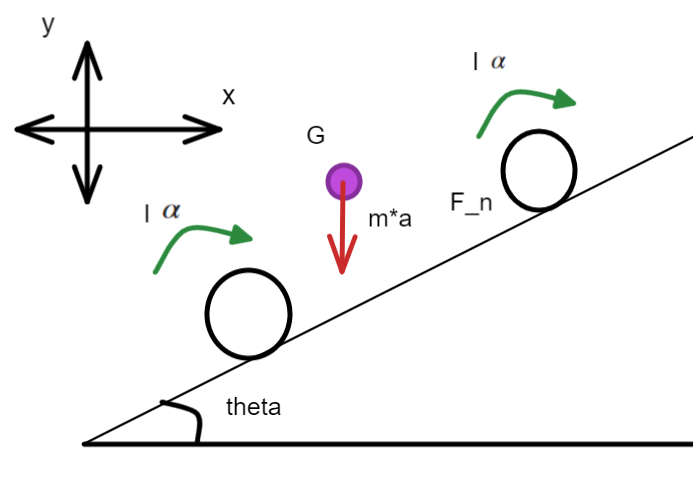

**b) **

**For den tilbagelagte strækning **(tror ikke helt jeg forstår opgaven)


$$s(t) = s_0 + v_0\cdot t + \frac{a \cdot t^2}{2}$$


Hastihed og acceleration findes ved at differentier


$$v(t) =v_0+ a \cdot t$$



$$a = a $$


**For rotation**


$$\theta = \theta_0 + \omega_0 \cdot t + \frac{\alpha_z \cdot t^2}{2}$$


Differentiering forgår på samme måde som ovenfor

**c)**

%data
clear
g = 9.81 %m/s2

g =          9.81


mb = 2265 %kg

mb =         2265


d1 = 1.6 %m

d1 =           1.6


d2 = 1.275 %m

d2 =         1.275


h1 = 0.483 %m

h1 =         0.483


theta = 15 %o

theta =     15


mu_S = 0.9

mu_S =           0.9


**x-retning pr aksel**


$$F_{frik,x} = m \cdot g \cdot \mu_S \cdot cos(\theta)$$



$$2 \cdot F_{frik,x} = m \cdot g \cdot \sin(\theta) - 2 \cdot m \cdot a_x \cdot \cos(\theta)$$


**y-retningen pr aksel**


$$F_{frik,y} = m \cdot g \cdot \mu_S \cdot sin(\theta)$$



$$2 \cdot F_{frik,y} = m \cdot g \cdot \cos(\theta) -  2 \cdot m \cdot a_y \cdot \sin(\theta)$$


**d)**

Vi sætter de to ligninger = hinanden og løser for $a_x$ og $a_y$ vi ser m kan divbideres væk der ganges med 4 i stedet for 2 for at få accelerationen ved alle 4 hjul

syms a_x a_y
F_frik_eq = 4 *  g * mu_S * cosd(theta) == g* sind(theta) + 4 * a_x * cosd(theta);

a_x = solve(F_frik_eq, a_x);
a_x_ = vpa(a_x, 6)

$$a\_x\_ = 8.17185$$

**Vi får såldes en acceleration på alle fire hjul på **$a_x = 8,17 \frac{m}{s^2}$

**e)**

Vi beregner kun for en akse da der kun er baghjulstræk

syms a_x a_y
theta = 0

theta =      0


F_frik_eq =  2 *  g * mu_S * cosd(theta) == g * sind(theta) + 2 * a_x * cosd(theta);

a_x = solve(F_frik_eq, a_x);
a_x_ = vpa(a_x, 6)

$$a\_x\_ = 8.829$$

**Vi får såldes en acceleration på de to hjul på **$a_x = 8,83 \frac{m}{s^2}$

## Opgave 3 

Mathias Bruun Houmøller  -  202006837

**a)**

clear
% Data:
m = 300 %kg

m =    300


de tre fjedere er i serie dermed fås

k = 3 *900 %N/m

k =         2700


de 2 viskose dæmpere er i serie og dermed fås

c = 2 * 1125 %Nꞏs/m

c =         2250


x0 = -1.0 %m (bemærk: negativ startposition)

x0 =     -1


v0 = 18 %m/s

v0 =     18



w_n = sqrt(k/m) %egensvingningen

w_n =      3


Egenfrekvensen er $\omega_n = 3,0\frac{rad}{s}$

**b)**

Dæmpningsrationen findes

zeta = c/(2 * m * w_n) % viscous damping factor or damping ratio

zeta =          1.25



if separateUnits(zeta) < 1
    disp('systemet er underdamped')
elseif separateUnits(zeta) == 1
    disp('systemet er critical damped')
else
    disp('systemet er overdamped')
end

systemet er overdamped


$\zeta = 1,25$**  og systemet er dermed overdæmpede.**

**c)**

Værdierne ved t = 0 findes for sted og hastighedsfunktionen

x_0 = x0 % m %start stedet

x_0 =     -1


V_0 = v0 % m/s %start hastigheden

V_0 =     18


t0 = 0

t0 =      0


t1 = 2

t1 =      2


Ligning (8/10) bruges til at opstille forskydningsligninen med vores data

forskriften findes ved at substituere de to røder $\lambda_!$ og $\lambda_2$ i ligningen for svigningen $x=A\cdot e^{\lambda t}$

I det vi ikke har nogle svigninger bliver det maximale udsving start posistion $x_0 = -1\ m$

således fås


$$A_1 = x_0 = -1\ m \\
A_2 = V_0 = 18 \frac{m}{s}$$


syms t
A_1 = x_0

A_1 =     -1


A_2 = V_0

A_2 =     18



x(t) = A_1 * exp((-zeta + sqrt(zeta^2 - 1)) * w_n * t) + A_2 * exp((-zeta -sqrt(zeta^2 - 1)) * w_n * t)

$$x(t) = 18\,{\mathrm{e}}^{-6\,t}-{\mathrm{e}}^{-\frac{3\,t}{2}}$$

**d)**

Der plottes en kurve over bevægelsen

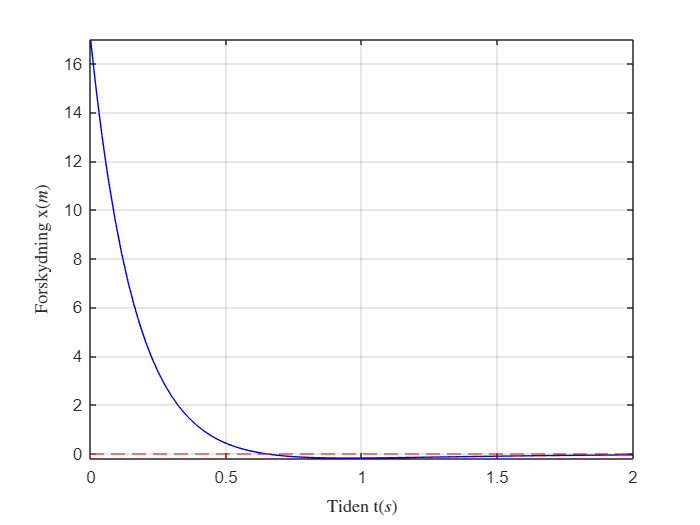

fplot(x(t), [t0, t1], Color='b') %plot 
hold on
yline(0, 'r--') %0 linje
ylabel('Forskydning x($m$)', Interpreter='latex')
xlabel('Tiden t($s$)', Interpreter='latex')
grid()
hold off

**f)**

Det maksimale udsving af massen xmax bliver start positionen $-1\ m$ da vi har overdæmpede svingninger men vi kan også få udsvingede i negativ retning efter slippet ved at differentier

x_1(t) = diff(x(t), t) %toppunktet findes

$$x\_1(t) = \frac{3\,{\mathrm{e}}^{-\frac{3\,t}{2}}}{2}-108\,{\mathrm{e}}^{-6\,t}$$


t_max = solve(x_1(t)==0, t) %tiden ved toppunktet løses

$$t\_max = \frac{2\,\log\left(72\right)}{9}$$


udsving = vpa(x(t_max),5) %x max ved top punktet

$$udsving = -0.18028$$

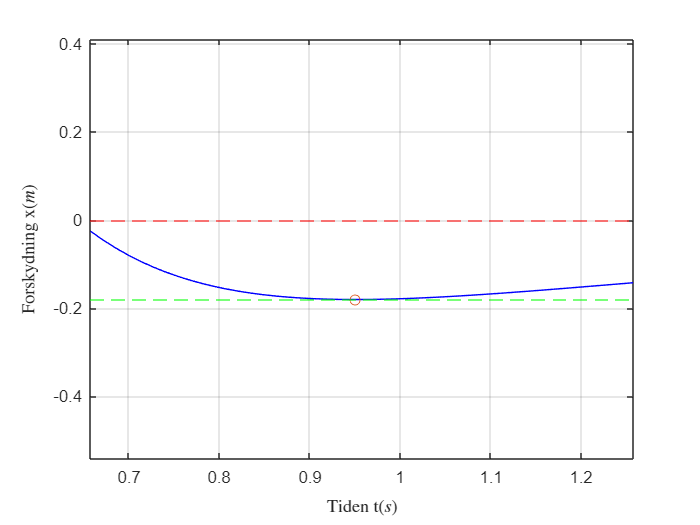


fplot(x(t), [t0, t1], Color='b') %plot 
hold on
yline(0, 'r--')
ylabel('Forskydning x($m$)', Interpreter='latex')
xlabel('Tiden t($s$)', Interpreter='latex')
grid()

yline(double(udsving), 'g--')
plot(t_max, udsving, 'o')
xlim([0.658 1.257])
ylim([-0.54 0.41])
hold off

**Dermed fås et udsving til **$-0,18\ m$